# Capstone project of Image Processing specialization by MathWorks on Coursera

*Soheil Solhjoo (2022)*

## Problem definition

A company has been struggling with heavy traffic outside of its office building. They want to measure traffic volume throughout the day. They provided a short video clip (RoadTraffic.mp4) taken from a camera they have set up on the roof. The goal is to count the number of cars in each frame as they drive by.

To being with, let's load the video and get some information about it.

vRGB = VideoReader("RoadTraffic.mp4")

vRGB =   VideoReader with properties:

   General Properties:
            Name: 'RoadTraffic.mp4'
            Path: 'C:\Users\P268670\OneDrive - University of Groningen\Documents\Work\Courses\Image Processing for Engineering and Science\Data\MathWorks Images'
        Duration: 24
     CurrentTime: 0.1000
       NumFrames: 240

   Video Properties:
           Width: 1158
          Height: 518
       FrameRate: 10
    BitsPerPixel: 24
     VideoFormat: 'RGB24'


fprintf('The area is %i pixels.\n', v.Height * v.Width)

The area is 599844 pixels.


## Preprocessing

After watching the video, two preprocessing steps seem to be required

- Converting the video into grayscale (because the passing cars have different colors), and

- Removing noise from the frames.

Let's first select one frame (frame #1) and apply our postprocessing.

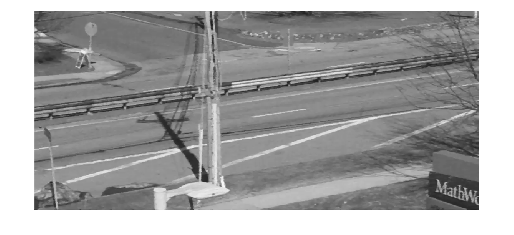

idx = 1;
frame = read(v,idx);

% RGB -> Grayscale
frame = rgb2gray(frame);
imshow(frame)

### Removing Noise

There are various spatial filters to be used. One promising one is the "Median Filter", which is good to remove salt and peper noise while preserving edges.

For creating a spatial filter, it size should be defined too. In here, a filter size of [m,n] = [3,6] is used.

m = 3;
n = floor(v.Width/v.Height * m);
imMed = medfilt2(frame,[m,n],"symmetric");
imshow(imMed)

Now, let's write a function (preprocess) to do the same thing on any given frame, and then export them as a new video for further processing.

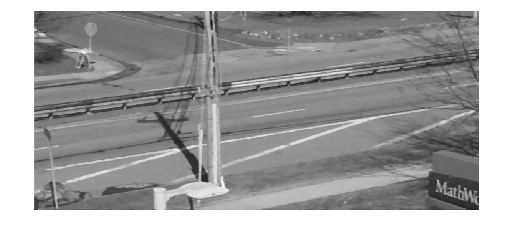

vGray = VideoWriter("RoadTraffic_01_pre.mp4",'MPEG-4');
vGray.FrameRate = vRGB.FrameRate;
open(vGray);

for idx = 1:v.NumFrames
    frame = preprocessing(read(v,idx),[m,n]);
    writeVideo(vGray,frame);
end

close(vGray);

## Isolating the cars

The next task is to use image segmentation to isolate the cars driving on the road. The end result of this section is to have a process for taking frames from the video and generates segmented masks. This way the cars can be reliably isolated from the video so that the number of regions detected equals the number of cars in the original frame.

We will work with the newly preprocessed video.

v = VideoReader("RoadTraffic_01_pre.mp4")

v =   VideoReader with properties:

   General Properties:
            Name: 'RoadTraffic_01_pre.mp4'
            Path: 'C:\Users\P268670\OneDrive - University of Groningen\Documents\Work\Courses\Image Processing for Engineering and Science\Course 3\Capstone'
        Duration: 24
     CurrentTime: 0.1000
       NumFrames: 240

   Video Properties:
           Width: 1158
          Height: 518
       FrameRate: 10
    BitsPerPixel: 24
     VideoFormat: 'RGB24'


Note that the video is saved as RGB24. One way to correct it is to change the profile of the vide in "writeVideo". We can also convert frames into grascale once we read them. The second approach is adopted here.

One main step to take is to remove the background from the forground. Let's choose frame #1 as the background, and try the idea on some different frames.

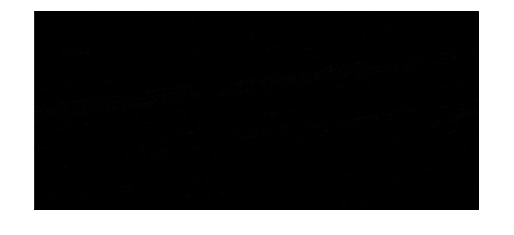

background = im2double(rgb2gray(read(v,1)));

max_frame = v.NumFrames;
idx = 2;
for i = idx
    frame = im2double(rgb2gray(read(v,i)));
    frameDiff = abs(frame - background);
    imshow(frameDiff)
end

A couple of issues can be identified:

- There is a pole that cut the identified cars in 2 pieces (for example, set *j=1*), and

- The identified cars are not fully differentiated from the background.

Let's try a closeing proecss on frame 10.

sedisk = strel("disk",30);
car_full = imclose(frameDiff, sedisk);
% imshow(car_full)

This morphology process eliminate almost both of the issues, althoug it introduces a new one. For example, in frame 151, two cars are very close to each other, and this process, merge them into one single object. It can be eliminated by varying the shape of the working lens to a rectangular one.

sedisk_rect = strel("rectangle",[20,40]);
car_full = imclose(frameDiff, sedisk_rect);
% imshow(car_full)

It solves the vertically joined cars, and also remove the effect of the pole. Yet, it introduces another artefact. For example, in frame 111, the car is not fully identified and it's burried in the noise. Therefore, we need to remove the extra noise first.

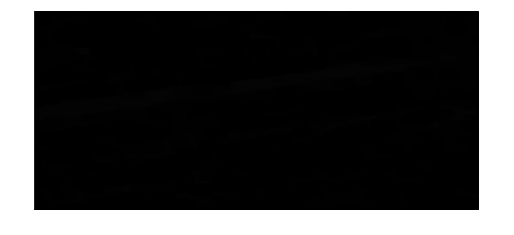

avg = fspecial("average",3);
im_smooth = imfilter(frameDiff,avg,"symmetric");
sedisk_rect = strel("rectangle",[20,40]);
car_full = imclose(im_smooth, sedisk_rect);
imshow(car_full)

Now we can make the segmentation.

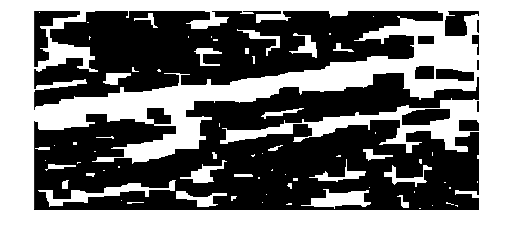

bw = imbinarize(car_full,"global");
imshow(bw)

Now, we should analyze the mask.

mask_props = regionprops("table",bw,"BoundingBox","Area");
num_cars = size(mask_props,1);

*num_cars* tells us the number of cars in each frame.

### Refinements

By walking through the video, we can find 2 issues with the current segmentation:

- It is easy to notice that when there is no car in the frame, the filtering process results in a large number of false positives, and

- Some outliers (false positives) also can be identified by the small area. These can be corrected by applying a lower limit threshold (for example: area_min = 100).

There are a number of different steps that can be taken to solve these issues.

- Adjust the contrast of the frames.

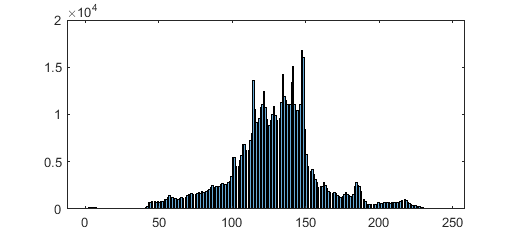

% Study the histogram of frame's intensity
frame_1 = rgb2gray(read(v,1));
histogram(frame_1)

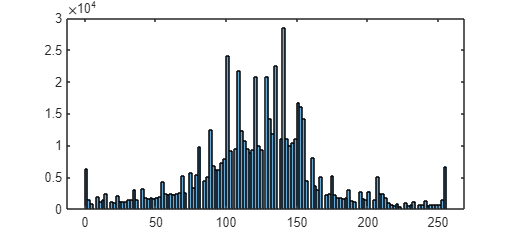

histogram(imadjust(frame_1))

histogram(adapthisteq(frame_1))

The histograms show that using an adaptive equilization expands the intensity, without introducing noise.

- Use various frames without cars to be used as the background; for example, the first 4 frames.

back_idx = 4;
background = im2double(adapthisteq(rgb2gray(read(v,1))));
for idx = 2:back_idx
    background = background + im2double(adapthisteq(rgb2gray(read(v,idx))));
end
background = background/back_idx;

- Define an upper limit (using frames without cars) to remove noises.

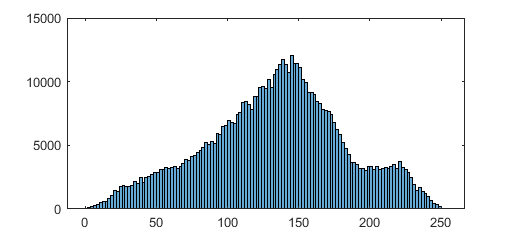

idx = 1;

frame = im2double(adapthisteq(rgb2gray(read(v,idx))));

frameDiff = abs(frame - background);
noise_thresh = max(frameDiff,[],"all")

noise_thresh = 0.2186

Studying the first 4 frames, the maximum noise level is found to be ~0.21:

- Removing the remaining background noise by introducing an averaging filter. I'll use the following for the filtering:

**Note:** this filtering should be done before removing the *noise_thresh*.

- Filling holes within the identified cars of the created mask.

- Deining a lower limit for the area of the identified cars. By inspection, one can see that the area of a car takes more than 500 pixels in each frame. By introducing such threshhold, we can remove the remaining false positives.

            This also can be done by applying the limit by bwpropfilt function:

### Exploration of the ideas

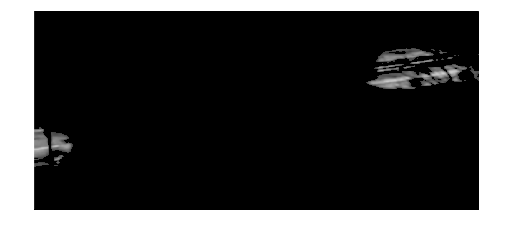

noise_thresh = 0.25;
% car_num_max = 5;
area_min = 500;

max_frame = v.NumFrames;
idx = 186;
frame = im2double(adapthisteq(rgb2gray(read(v,idx))));
frameDiff = abs(frame - background);
frameDiff = imfilter(frameDiff,fspecial("average",5),"symmetric");
frameDiff(frameDiff <= noise_thresh) = 0;
imshow(frameDiff)


sedisk_rect = strel("rectangle",[10,40]);
car_full = imclose(frameDiff, sedisk_rect);
bw = imbinarize(car_full);
bw = imfill(bw, 'holes');
bw = bwpropfilt(bw,'Area',[area_min inf]);
mask_props = regionprops("table",bw,"BoundingBox","Area");
% mask_props(mask_props.Area < area_min,:) = [];

num_cars = size(mask_props,1)

num_cars = 2

total_area = sum(mask_props.Area)

total_area = 27857

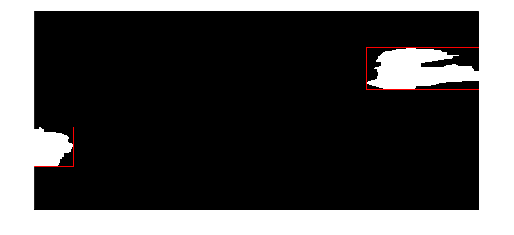

imshow(insertShape(im2double(bw),"Rectangle",mask_props.BoundingBox,"linewidth",2,"color","red"));

## Analyzing all frames and Exporting a video with boxed cars

Now that we have a process for segmenting cars, we'll need to apply it to the whole video so that we can statistically analyze the regions found in each frame. To summarize the region information for each frame, we can create a table that contains a row for each frame of the video and a column for the following three properties:

- number of regions

- mean region size

- total region size

First, let's create a function (processing) to perform all different processing steps in a frame. Then, we'll pass each frame to this function and analyze its output.

### Some further changes:

- It's easier to update the preprocessing function to directly apply "adapthisteq" there, and

- We can write the final code without the need of preparing that gray video, that we used earlier to perform some studies.

- For exporting the video, we'll draw a box around the identified cars.

The following is the final code for this project:

vRGB = VideoReader("RoadTraffic.mp4");

vBox = VideoWriter("RoadTraffic_boxed.mp4","MPEG-4");
vBox.FrameRate = vRGB.FrameRate;

filt_width = 3;
filt_height = floor(vRGB.Width/vRGB.Height * filt_width);
back_idx = 4;
noise_thresh = 0.2;
area_min = 500;

background = im2double(preprocessing(read(vRGB,1),[filt_width,filt_height]));
for idx = 2:back_idx
    background = background + im2double(preprocessing(read(vRGB,idx),[filt_width,filt_height]));
end
background = background / back_idx;


carData = zeros(vRGB.NumFrames,3);
open(vBox);
for idx = 1:vRGB.NumFrames
    frame = im2double(preprocessing(read(vRGB,idx),[filt_width,filt_height]));
    carInfo = processing(frame,background,noise_thresh);
    carInfo(carInfo.Area < area_min,:) = [];
    carData(idx,:) = [size(carInfo,1) mean(carInfo.Area,"all") sum(carInfo.Area,"all")];

    carBoxed = insertShape(read(vRGB,idx),"Rectangle",carInfo.BoundingBox,"linewidth",3,"color","yellow");
    writeVideo(vBox,carBoxed);
end
close(vBox);

## Some further analysis

Now, let's perform some analyses, and answer some relevant questions.

NumberRegions = carData(:,1);
MeanRegionSize = carData(:,2);
TotalRegionSize = carData(:,3);
carInfo = table(NumberRegions,MeanRegionSize,TotalRegionSize);

*How many frames of the video does your algorithm detect at least one car?*

frames_with_cars = nnz(carInfo.NumberRegions)

frames_with_cars = 158

*What is the *[*mode value*](https://www.mathworks.com/help/matlab/ref/mode.html)* for the number of cars detected in a frame?*

mode_of_cars = mode(carInfo.NumberRegions)

mode_of_cars = 1

*What is the average size of a region in terms of the number of pixels?*

wcar = carInfo.NumberRegions == 0;
mean_size = sum(carInfo.TotalRegionSize(~wcar),"omitnan") / sum(carInfo.NumberRegions)

mean_size = 1.6549e+04

## Functions

The functions for various steps are listed below.

### Preprocessing

function frame = preprocessing(frame,filter_size)

% frame = medfilt2(rgb2gray(frame),filter_size,"symmetric");
frame = adapthisteq(medfilt2(rgb2gray(frame),filter_size,"symmetric"));

end

### Processing

function props = processing(frame,background,noise_thresh)

frame   = abs(frame - background);
frame   = imfilter(frame,fspecial("average",5),"symmetric");
frame(frame <= noise_thresh) = 0;
se_rect = strel("rectangle",[10,40]);
frame   = imclose(frame, se_rect);
bw      = imbinarize(frame);
bw      = imfill(bw, 'holes');
props   = regionprops("table",bw,"BoundingBox","Area");

end